# SMC

Diseño y simulación de un controlador de modo deslizante para un modelo simplificado de un motor dc. 

clear; clc; close all; lambda1 = 0; lambda2 = 0; delta_x1 = 0; 

Propiedades del motor

load("TF.mat")

## 1. Cálculo del beta

beta=40

beta = 40

MAX_PWM=80

MAX_PWM = 80

a=1

a = 1

delta=95*pi/180

delta = 1.6581

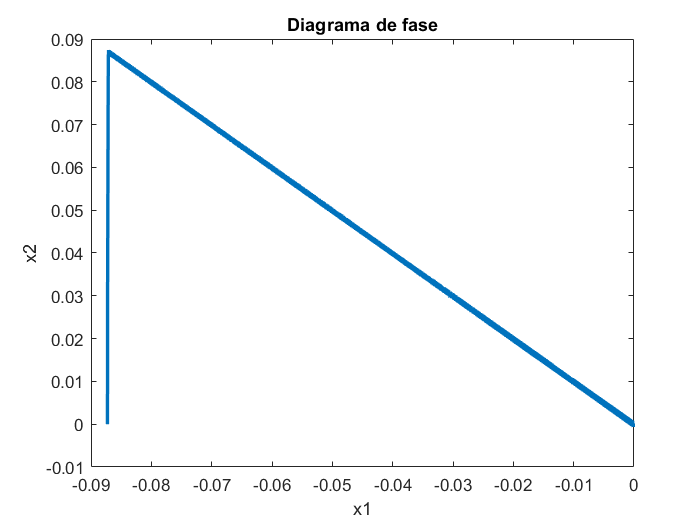


results = sim("smcSL.slx");

t = results.tout; % tiempo de simulación

% Estados del sistema
x1 = results.errorTheta.Data;
x2 = results.Omega.Data;

figure(); 


plot(x1, x2, '-', 'LineWidth',2); hold on; 
title("Diagrama de fase"); 
xlabel("x1"); ylabel("x2"); 

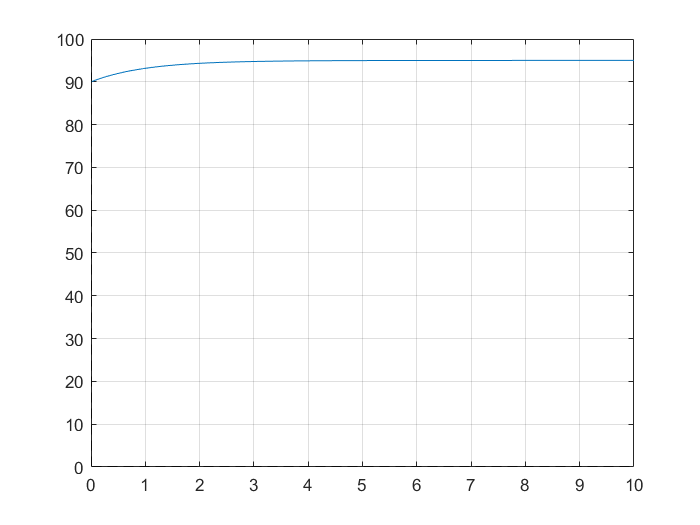


figure()

plot(t,results.Theta.Data*180/pi)
xline(0, 'k--'); yline(0, 'k--'); 
grid on; 

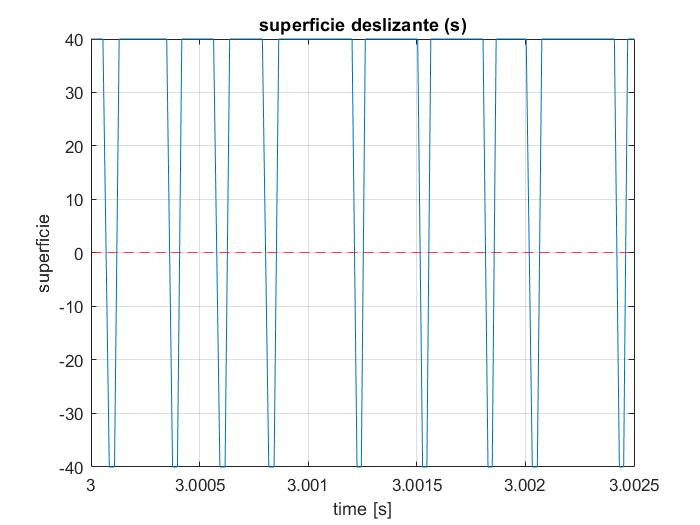


figure()

plot(t, results.U.Data); hold on; 
yline(0, 'r--'); 
title("superficie deslizante (s)")
xlabel("time [s]"); 
ylabel("superficie"); 
grid on; 
hold off; 


xlim([3 3.0025])

% condiciones iniciales 
x10 = -pi/2; 
x20 = 0; 

delta_x1 = 0; %-pi/6; 

results = sim("SMC_comparativa.slx"); 

t = results.tout; % tiempo de simulación    

% Estados del sistema
x1 = results.x1.Data;
x2 = results.x2.Data;


figure(); 
subplot(2, 1, 1);

% superficie deslizante 
x = -5:0.01:5; 
plot(x, -a*x);  hold on; 

plot(x1, x2, '-', 'LineWidth',2); hold on; 
title("Diagrama de fase"); 
xlabel("x1"); ylabel("x2"); 
axis([-abs(x10) * 1.2, abs(x10) * 1.2, -4, 4]); 
scatter(x10 - delta_x1, x20, 'r*'); 



xline(0, 'k--'); yline(0, 'k--'); 
grid on; 

subplot(2, 1, 2);

% Superficie deslizante 
s = results.s.Data; 


plot(t, s); hold on; 
yline(0, 'r--'); 
title("superficie deslizante (s)")
xlabel("time [s]"); 
ylabel("superficie"); 
grid on; 
hold off; 


figure(); 
plot(t, x1, t, x2)
yline(delta_x1)
hold off; legend("\theta", "\omega")